clear all;
close all;

u= readtable('ctrl_inputs.csv');

x= readtable('states.csv');
time= readtable('time.csv');

kappa_opt= readtable('kappa_opt.csv');

kappa_cen= readtable('kappa_center.csv');

path_og= readtable('track_smooth.csv');

path_opt= readtable('traj_opt.csv');

s_og= readtable('length_center.csv');

s_opt= readtable('length_opt.csv');

london_outer=readtable('london_outer.csv');

london_inner=readtable('london_inner.csv');

num_start=1;
num_end= 940;
plot_num= num_start:num_end;

**plot track outline**

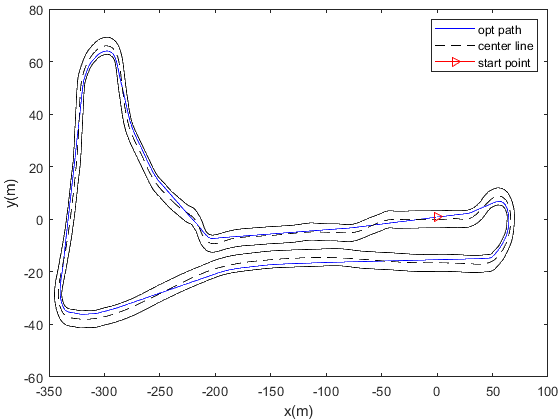

figure();
close;
plot(path_opt.x_Traj_x(plot_num), path_opt.traj_y(plot_num), 'blue', "LineWidth", 0.5)
hold on
plot(path_og.x_Track_x(plot_num), path_og.track_y(plot_num), 'black', "LineWidth", 0.5, "LineStyle","--")
hold on;
plot(path_opt.x_Traj_x(1), path_opt.traj_y(1), 'red', "marker",">")
hold on;
plot(london_outer.x_X, london_outer.y, 'black', 'LineWidth', 0.5)
hold on;
plot(london_inner.x_X, london_inner.y, 'black','LineWidth', 0.5)
hold off;
%grid on; grid minor; 
legend('opt path', 'center line', 'start point',  "Location", 'Northeast')
xlabel('x(m)');
ylabel('y(m)');
set(gca,'LooseInset',get(gca,'TightInset'))

**plot variables**

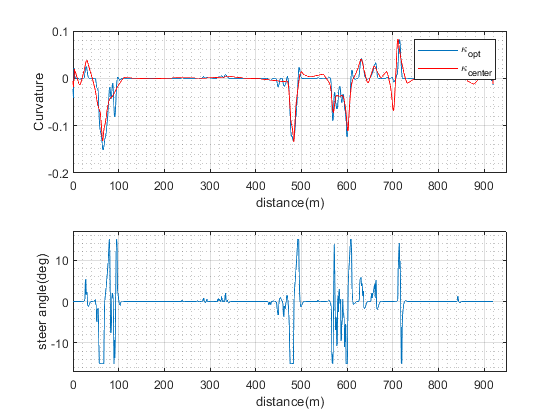

s_cumsum= cumsum(s_opt.x_S_opt);

figure;

subplot(2,1,1)
plot(s_cumsum(plot_num),kappa_opt.x_Kappa_opt(plot_num))
hold on;
plot(s_cumsum(plot_num),kappa_cen.x_Kappa_center(plot_num),'red')
hold off;
grid on; grid minor;
legend('\kappa_{opt}', '\kappa_{center}')
xlim([0,950])
xlabel('distance(m)')
ylabel('Curvature')

subplot(2,1,2)
plot(s_cumsum(plot_num),u.x_Delta(plot_num)*(180/pi))
grid on; grid minor;
xlim([0,950])
ylim([-17, 17])
xlabel('distance(m)')
ylabel('steer angle(deg)')





% subplot(2,1,2)
% plot(s_cumsum(plot_num),x.Var1(plot_num)*(3.6));
% grid on; grid minor;
% title('Speed (km/h)')
% 
% subplot(4,1,4)
% plot(s_cumsum(plot_num),u.F_drive(plot_num)/(1091))
% hold on;
% plot(s_cumsum(plot_num),u.F_brake(plot_num)/(1800))
% hold off;
% grid on; grid minor;
% legend('F_{dri}', 'F_{brk}')
% xlabel('distance(m)')
% title('Effort (normalized)')


% speed vs drive effort
% figure();
% plot(time.x_T_(plot_num),x.Var1(plot_num)*(3.6)/25);
% hold on;
% plot(time.x_T_(plot_num),u.F_drive(plot_num)/(1091));
% hold off;
% grid on; grid minor;
